# Stability Analysis

Analysis stability of signal by comparing first half data and second half data.

#### Pre-processing:

load('dTT_SYN_18Pair_R3_042619_UPD_cellROIs.mat')
% remove contamination
dis_th=40;
[E,~]=remove_contamination(E,dis_th);

ans = 'Pair1,Mouse1,97(58%) cells removed'

ans = 'Pair1,Mouse2,40(20%) cells removed'

ans = 'Pair2,Mouse1,6(8.5%) cells removed'

ans = 'Pair2,Mouse2,40(39%) cells removed'

ans = 'Pair3,Mouse1,39(53%) cells removed'

ans = 'Pair3,Mouse2,90(36%) cells removed'

ans = 'Pair4,Mouse1,54(34%) cells removed'

ans = 'Pair4,Mouse2,129(55%) cells removed'

ans = 'Pair5,Mouse1,31(25%) cells removed'

ans = 'Pair5,Mouse2,100(38%) cells removed'

ans = 'Pair6,Mouse1,55(46%) cells removed'

ans = 'Pair6,Mouse2,98(41%) cells removed'

ans = 'Pair7,Mouse1,108(41%) cells removed'

ans = 'Pair7,Mouse2,65(44%) cells removed'

ans = 'Pair8,Mouse1,3(4.2%) cells removed'

ans = 'Pair8,Mouse2,58(36%) cells removed'

ans = 'Pair9,Mouse1,18(17%) cells removed'

ans = 'Pair9,Mouse2,32(17%) cells removed'

ans = 'Pair10,Mouse1,113(50%) cells removed'

ans = 'Pair10,Mouse2,86(54%) cells removed'

ans = 'Pair11,Mouse1,30(23%) cells removed'

ans = 'Pair11,Mouse2,69(47%) cells removed'

ans = 'Pair12,Mouse1,76(52%) cells removed'

ans = 'Pair12,Mouse2,61(40%) cells removed'

ans = 'Pair13,Mouse1,53(25%) cells removed'

ans = 'Pair13,Mouse2,59(25%) cells removed'

ans = 'Pair14,Mouse1,84(48%) cells removed'

ans = 'Pair14,Mouse2,51(22%) cells removed'

ans = 'Pair15,Mouse1,83(34%) cells removed'

ans = 'Pair15,Mouse2,89(38%) cells removed'

ans = 'Pair16,Mouse1,57(33%) cells removed'

ans = 'Pair16,Mouse2,87(32%) cells removed'

ans = 'Pair17,Mouse1,64(27%) cells removed'

ans = 'Pair17,Mouse2,84(30%) cells removed'

ans = 'Pair18,Mouse1,69(25%) cells removed'

ans = 'Pair18,Mouse2,72(27%) cells removed'

#### 1.Compare first PC coefficient in the first half and second half

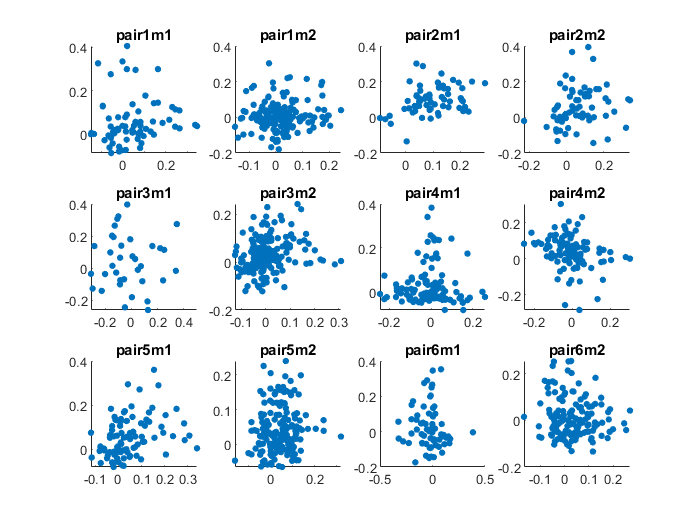

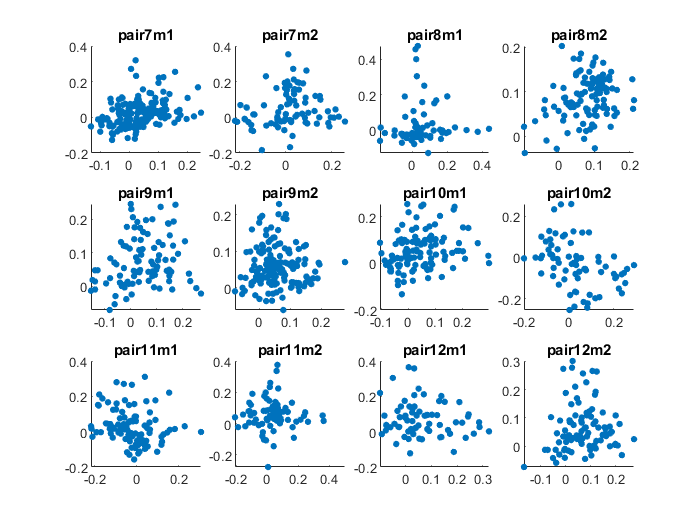

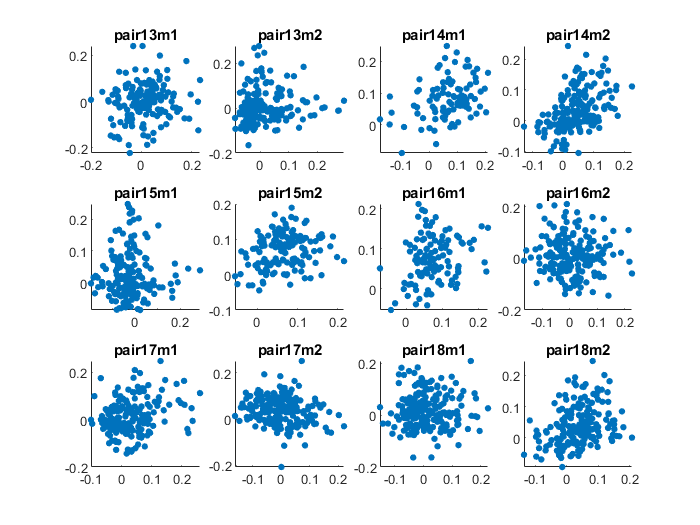

close all
for i=1:3
    figure(i)
    c=0;
    for p=6*(i-1)+1:6*i
        for m=1:2
            c=c+1;
            ca=zscore(E{p}{m}.dFFCalciumTraces); % each cell is centered at 0
            len=floor(size(ca,1)/2);
            [coef1,score1,~,~,~,mu1]=pca(ca(1:len,:));
            [coef2,score2,~,~,~,mu2]=pca(ca(len+1:end,:));
            subplot(3,4,c)
            scatter(coef1(:,1),coef2(:,1),15,"filled")
            title(sprintf('pair%dm%d',p,m))
        end
    end
end

#### 2. project second half data on the PCs of first half and compare correlation between cell populations 

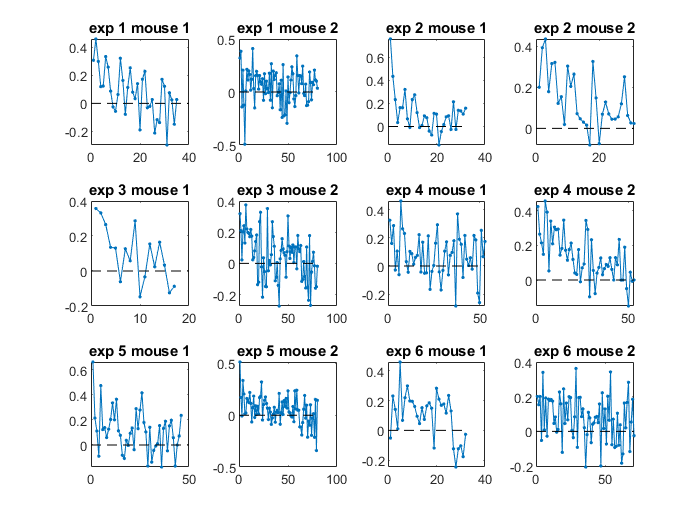

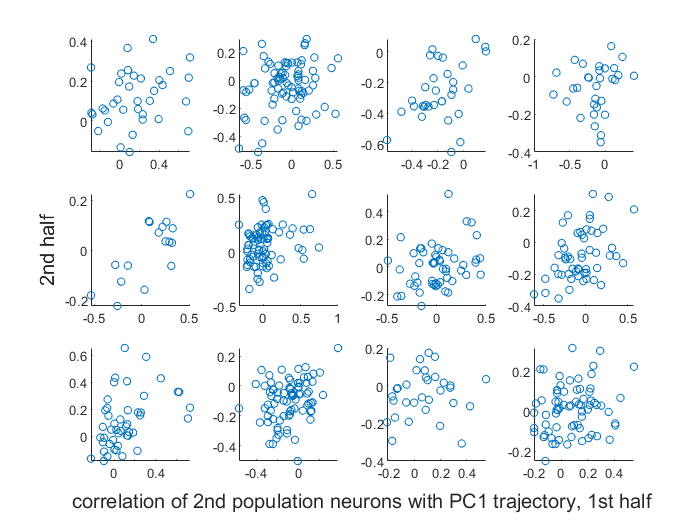

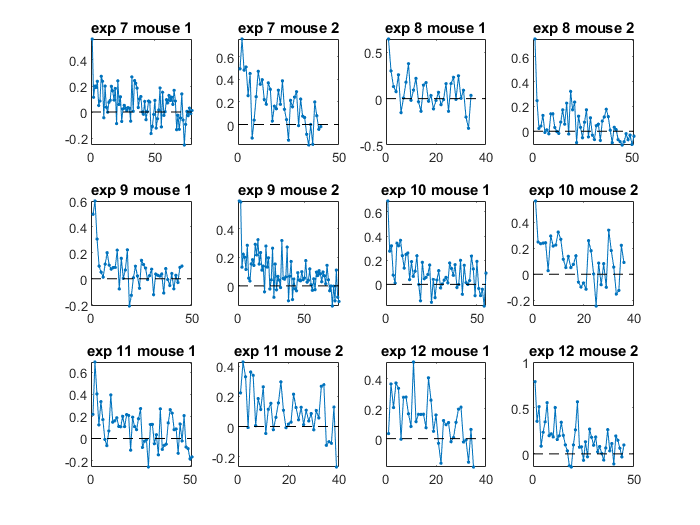

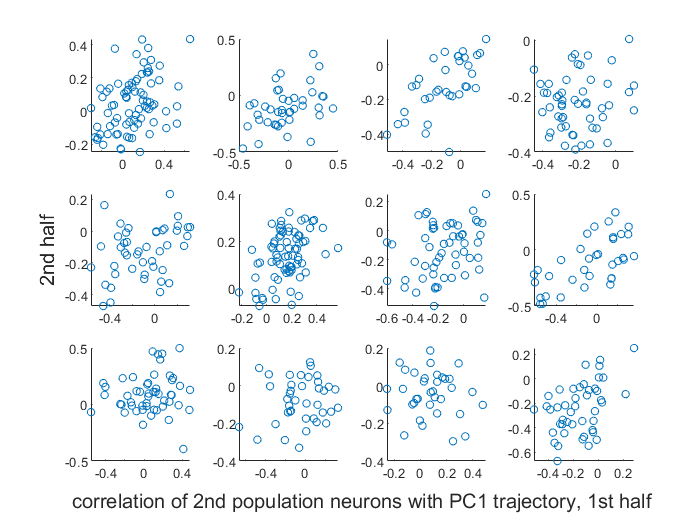

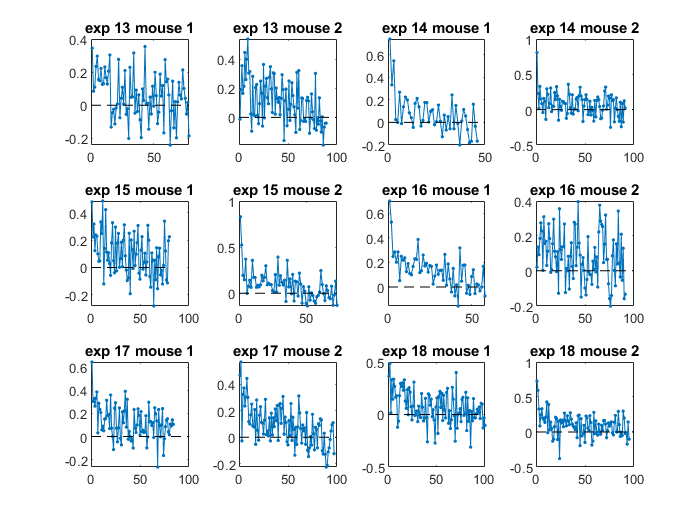

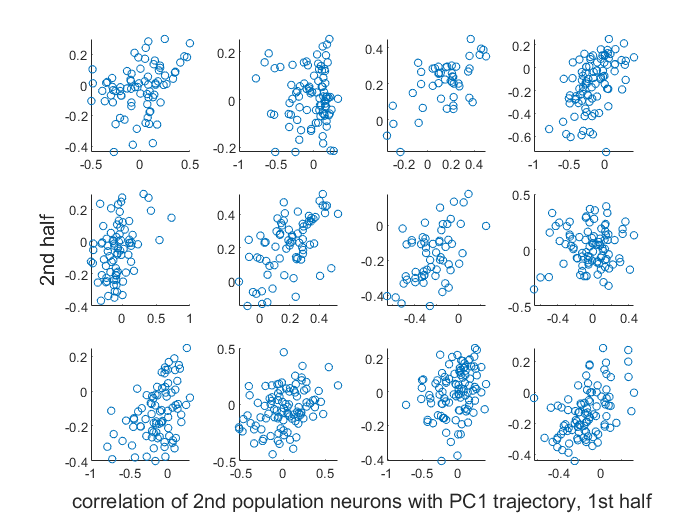

close all
for i=1:3
    figure(2*i-1)
    t1=tiledlayout(3,4);
    figure(2*i)
    t2=tiledlayout(3,4);
    xlabel(t2,'correlation of 2nd population neurons with PC1 trajectory, 1st half')
    ylabel(t2,'2nd half')
    for p=6*i-5:6*i
        for m=1:2
            X = zscore(compressMatrix(E{p}{m}.dFFCalciumTraces, 30, 1))';
            [U,V,x,cx,rst1tr,rst1te,rst2tr,rst2te]=stability_dimensions(X);
            figure(2*i-1)
            nexttile
            plot(cx, '.-')
            title(sprintf('exp %d mouse %d', p, m))
            hold on, plot(xlim, [0 0], 'k--'); hold off
            figure(2*i)
            nexttile
            scatter(corr([U(:, 1)' * rst1tr]', rst2tr'), corr([U(:, 1)' * rst1te]', rst2te'),20)
        end
    end
end

#### 3 Power stability of population rate 

The mean power in 7 specified frequency ranges over first and second halves of the signal. Signals of 75 neurons in 10 minutes were taken from each animal. 

W = {[1 10] [0.1 1] [0.05 0.1] [0.025 0.05] [0.0125 0.025] [0.00625 0.0125]};
ncell=75;nsecond=600;
k=0;
for p=1:18
    for m=1:2
        [nf,nc]=size(E{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            continue
        end
        k=k+1;
        takecell=ceil(nc*rand(ncell,1));
        for f=1:length(W)
            ca=mean(zscore(E{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
            ca1 = ca(1:round(end/2)); % divide into two halves
            ca2 = ca(1+round(end/2):end);
            bpca(k,f,1)=bandpower(ca1,30,W{f});% mean power in specified ranges
            bpca(k,f,2)=bandpower(ca2,30,W{f});
        end
    end
end
f=figure;f.Position(3)=1.5*f.Position(3);
t=tiledlayout(2,4,'TileSpacing',"compact");
for f=1:length(W)
    nexttile
    scatter(bpca(:,f,1),bpca(:,f,2),15,'filled')
    xlim([0 max([bpca(:,f,1);bpca(:,f,2)])]);ylim([0 max([bpca(:,f,1);bpca(:,f,2)])])
    axis square 
    title(sprintf('%gto%gHz',W{f}(1),W{f}(2)))
end
title(t,'Mean power at frequency ranges in 1st and 2nd half of signal')

#### 4 number of population events

Number of population events in animals in first and second half of the signal. Signals of 100 neurons in 10 minutes were taken from each animal. 

N=18;ca_cl=cell(20,2);ncell=100;nsecond=600;c=0;
for p =1:N
    for m =1:2
        [nf,nc]=size(E{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            continue
        end
        c=c+1;
        takecell=ceil(nc*rand(ncell,1));
        ca=zscore(E{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)); % mean of 75 random cells in 10 minutes
        ca1 = ca(1:round(end/2),:); % divide into two halves
        ca2 = ca(1+round(end/2):end,:);
        ca_cl{c,1}=normalizeca(ca1);
        ca_cl{c,2}=normalizeca(ca2);
    end
end
em=events_1r(ca_cl); % 1st round events at 0.5 threshold
em2=events_2r(ca_cl,em{1,1}.ne); % 2nd round at 0.5 threshold, at time that does not have event in the first round
em{2,1}=em2{1,1};
em=rem_dup_em(em); % remove m duplicate
klist={5,20,40};% find events separately for each k

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


ev_merge=cell(c,2);
for r=1:2 % two rounds
    allt=cell(c,2);allm=cell(c,2);allk=cell(c,2);
    for m=1:c
        for h=1:2
            [allt{m,h},allm{m,h},allk{m,h}]=alltmk(klist,em{r,1}.K{m,h},em{r,1}.M{m,h},em{r,1}.time{m,h});
        end
    end
    em{r,1}.allt=allt;em{r,1}.allm=allm;em{r,1}.klist=klist;em{r,1}.allk=allk;
end
for m=1:c % combine events from two rounds of detection
    for h=1:2
        for k=1:length(klist)
            ev_merge{m,h}{k}=combine_2_r(em{1,1}.allt{m,h}{k},find(em{2,1}.timefilter{m,h}),em{2,1}.allt{m,h}{k},'position','center',"k",klist{k});
            ev_merge{m,h}{k}=remove_time_ovp(ev_merge{m,h}{k},klist{k}); % remove highly overlapped events in time
        end
    end
end
% plot number of events in two halves
f=figure;f.Position(4)=0.5*f.Position(4);
t=tiledlayout(1,3);
n1=zeros(length(klist),size(ev_merge,1));n2=zeros(length(klist),size(ev_merge,1));
for k=1:length(klist)
    for i=1:length(n1)
        n1(k,i)=length(ev_merge{i,1}{k});n2(k,i)=length(ev_merge{i,2}{k});
    end
    nexttile
    scatter(n1(k,:),n2(k,:),12,'filled')
    title(sprintf('K=%g',klist{k}))
end

#### 5 number of population antievents

Number of population antievents in animals in first and second half of the signal. Signals of 100 neurons in 10 minutes were taken from each animal. 

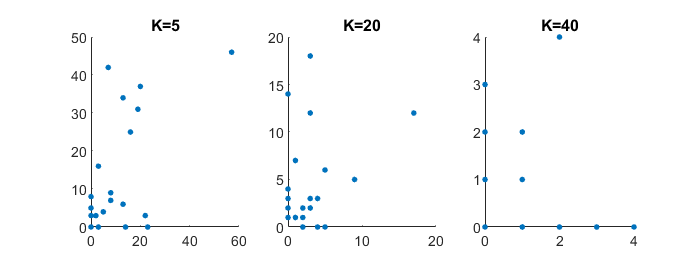

N=18;ca_cl=cell(20,2);ncell=100;nsecond=600;c=0;
for p =1:N

    for m =1:2
        [nf,nc]=size(E{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            continue
        end
        c=c+1;
        takecell=ceil(nc*rand(ncell,1));
        ca=zscore(E{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)); % mean of 75 random cells in 10 minutes
        ca1 = ca(1:round(end/2),:); % divide into two halves
        ca2 = ca(1+round(end/2):end,:);
        ca_cl{c,1}=normalizeca(ca1);
        ca_cl{c,2}=normalizeca(ca2);
    end
end
anti=events_1r(ca_cl,"type","anti","thre",0.05); 
em=rem_dup_em(em); % remove m duplicate
klist={5,20,40};% find events separately for each k
ev_merge=cell(c,2);
for m=1:c % combine events from two rounds of detection
    for h=1:2

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


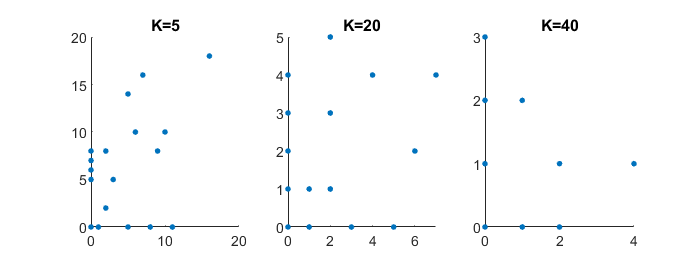

        [allt{m,h},allm{m,h},allk{m,h}]=alltmk(klist,anti{1,1}.K{m,h},anti{1,1}.M{m,h},anti{1,1}.time{m,h});
        ev_merge{p,m}=cell(1,length(klist));
        for k=1:length(klist)
            ev_merge{m,h}{k}=allt{m,h}{k}+klist{k}/2;
            ev_merge{m,h}{k}=remove_time_ovp(ev_merge{m,h}{k},klist{k});
        end
    end
end
% plot number of events in two halves
f=figure;f.Position(4)=0.5*f.Position(4);
t=tiledlayout(1,3);
n1=zeros(length(klist),size(ev_merge,1));n2=zeros(length(klist),size(ev_merge,1));
for k=1:length(klist)
    for i=1:length(n1)
        n1(k,i)=length(ev_merge{i,1}{k});n2(k,i)=length(ev_merge{i,2}{k});
    end
    nexttile
    scatter(n1(k,:),n2(k,:),12,'filled')
    title(sprintf('K=%g',klist{k}))
end